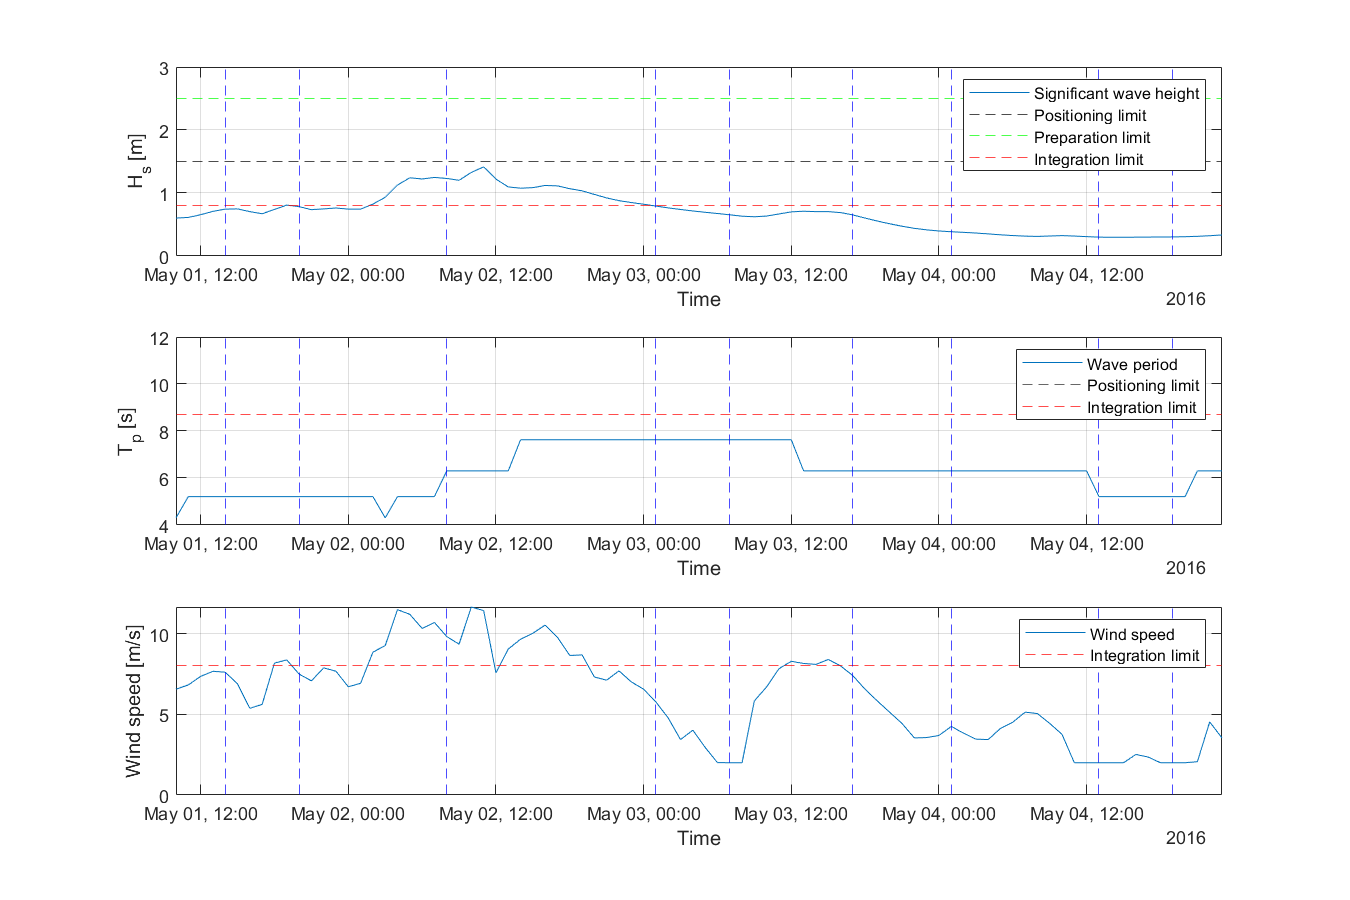

clc
clear 
close all

%% This code serves to create the weather waiting figure

% Read the CSV file
data = readtable('MetData/2016.csv');


% Extract the relevant columns
time = data.time;
ff = data.ff;
hs = data.hs;
tp = data.tp;

% Convert time column to MATLAB's datetime format
time = datetime(time, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

% Define the start and end dates for the desired period
startDate = datetime(2016, 5, 1, 10, 0, 0);
endDate = datetime(2016, 5, 4, 23, 0, 0); % Assuming hourly data
startTime = datetime(2016, 5, 1, 10, 0, 0);
% Find the indices corresponding to the desired period
indices = time >= startDate & time <= endDate;

% Extract the data for the desired period
time_period = time(indices);
ff_period = ff(indices);
hs_period = hs(indices);
tp_period = tp(indices);

HsTransit=3;
HsPosi=1.5;
HsConn=2.5;
HsInst=0.8;
TpInst=8.7;
TpPos=12;
WindInst=8;

Tpos=4;
Tload=3*2+Tpos;
Tcon=3*4+Tload;
Twait1=17+Tcon;
Ttow=6+Twait1;
Twait2=10+Ttow;
Tnac=8+Twait2;
TBlade=4*3+Tnac;
Tcom=6+TBlade;
time_Tpos = startTime + hours(Tpos);
time_Tload = startTime + hours(Tload);
time_Tcon = startTime + hours(Tcon);
time_Twait1= startTime + hours(Twait1);
time_Ttow = startTime + hours(Ttow);
time_Twait2= startTime + hours(Twait2);
time_Tnac = startTime + hours(Tnac);
time_TBlade = startTime + hours(TBlade);
time_Tcom = startTime + hours(Tcom);


f1=figure('Renderer', 'painters', 'Position', [10 10 900 600]);

% Subplot 1: Wave Height (hs)
subplot(3, 1, 1);
plot(time_period, hs_period);
yline(HsPosi,'k--')
yline(HsConn,'g--')
yline(HsInst,'r--')
xline(time_Tpos,'b--')
xline(time_Tload,'b--')
xline(time_Tcon,'b--')
xline(time_Twait1,'b--')
xline(time_Ttow,'b--')
xline(time_Twait2,'b--')
xline(time_Tnac,'b--')
xline(time_TBlade,'b--')
xline(time_Tcom,'b--')
xlabel('Time');
ylabel('H_s [m]');
xlim([startTime, endDate]);
grid on
legend('Significant wave height','Positioning limit','Preparation limit','Integration limit')

% Subplot 2: Wave Period (tp)
subplot(3, 1, 2);
plot(time_period, tp_period);
yline(TpPos,'--')
yline(TpInst,'r--')
xline(time_Tpos,'b--')
xline(time_Tload,'b--')
xline(time_Tcon,'b--')
xline(time_Twait1,'b--')
xline(time_Ttow,'b--')
xline(time_Twait2,'b--')
xline(time_Tnac,'b--')
xline(time_TBlade,'b--')
xline(time_Tcom,'b--')
xlabel('Time');
ylabel('T_p [s]');
xlim([startTime, endDate]);
grid on
legend('Wave period','Positioning limit','Integration limit')

% Subplot 3: Wind Speed (ff)
subplot(3, 1, 3);
plot(time_period, ff_period);
yline(WindInst,'r--')
xline(time_Tpos,'b--')
xline(time_Tload,'b--')
xline(time_Tcon,'b--')
xline(time_Twait1,'b--')
xline(time_Ttow,'b--')
xline(time_Twait2,'b--')
xline(time_Tnac,'b--')
xline(time_TBlade,'b--')
xline(time_Tcom,'b--')
xlabel('Time');
ylabel('Wind speed [m/s]');
xlim([startTime, endDate]);
grid on
legend('Wind speed','Integration limit')

exportgraphics(f1,'EnvTimeSeries.pdf')